# Solve DAE for cart-pole system

Based on this example from documentation:

- [https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html](https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html)

clear variables

results_dir = 'results';
if ~isfolder(results_dir)
    mkdir(results_dir)
end

Equations and diagram below from:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system.

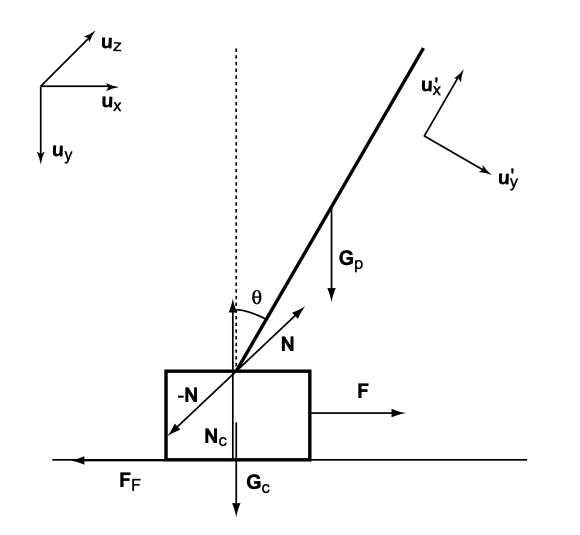

State variables

- Horizontal position of cart (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of pole (clockwise from vertical up position) $\theta \left(t\right)$

- Angular velocity of pole $\dot{\;\theta \;} \left(t\right)$

Other variables

- Downwards force on track from cart $N_c \left(t\right)$

- Frictional force exerted on cart by track $F_F \left(t\right)$

- Force exerted on cart by pole (and vice versa) $N\left(t\right)$

Potential input variables

- Horizontal diriving force on cart $F\left(t\right)$

Parameters

- Cart mass $m_c$

- Pole mass $m_p$

- Pendulum length $l$

- Acceleration due to gravity $g$

- Coefficient of friction for cart and track $\mu_c$

- Coefficient of friction for pole and cart joint $\mu_p$

System of DAEs


$$\begin{array}{l}
N_c =\left(m_c +m_p \right)g-m_p l\left(\ddot{\theta} \;\sin \theta +{\dot{\theta} }^2 \;\cos \theta \right)\\
\ddot{\theta} =\frac{g\;\sin \theta +\cos \theta \left\lbrace \frac{-F-m_p l{\dot{\theta} }^2 \left(\sin \theta +\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\cos \theta \right)}{m_c +m_p }+\mu_c g\;\textrm{sgn}\left(N_c \dot{x} \right)\right\rbrace -\frac{\mu_p \dot{\theta} }{m_p l}}{l\left\lbrace \frac{4}{3}-\frac{m_p \cos \theta }{m_c +m_p }\left(\cos \theta -\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\right)\right\rbrace }\\
\ddot{x} =\frac{F+m_p l\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \textrm{sgn}\left(N_c \dot{x} \right)}{m_c +m_p }
\end{array}$$


## First, define an autonomous system

i.e. `F(t) = 0`, `L(t) = l` (constant)

syms x(t) theta(t) Nc(t) F mc mp l g muc mup

eqn1 = 1000 * Nc == ...
    (mc + mp) * g - mp * l * (diff(theta(t), 2) * sin(theta(t)) + diff(theta(t))^2 * cos(theta(t)))

$$eqn1(t) = 1000\,\mathrm{Nc}\left(t\right)=g\,\left(\mathrm{mc}+\mathrm{mp}\right)-l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)$$

eqn2 = diff(theta(t), 2) == ...
    (g * sin(theta(t)) + cos(theta(t)) * ( ...
        (-F - mp * l * diff(theta(t))^2 * (sin(theta(t)) + muc * sign(Nc) * sign(diff(x(t))) * cos(theta(t))) ...
     ) / (mc + mp) + muc * g * sign(Nc) * sign(diff(x(t)))) - mup * diff(theta(t)) / (mp * l) ) ...
    / (l * (4/3 - mp * cos(theta(t)) / (mc + mp) * (cos(theta(t)) - muc * sign(Nc) * sign(diff(x(t))))))

$$eqn2(t) = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{\cos\left(\theta \left(t\right)\right)\,\left(\frac{F+l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)+\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\sigma_{1}\,\cos\left(\theta \left(t\right)\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{\mathrm{mc}+\mathrm{mp}}-g\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\sigma_{1}\right)-g\,\sin\left(\theta \left(t\right)\right)+\frac{\mathrm{mup}\,\frac{\partial }{\partial t}\theta \left(t\right)}{l\,\mathrm{mp}}}{l\,\left(\frac{\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\left(\cos\left(\theta \left(t\right)\right)-\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\sigma_{1}\right)}{\mathrm{mc}+\mathrm{mp}}-1.3333\right)}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{sign}\left(\frac{\partial }{\partial t}x\left(t\right)\right) \end{array}$$

eqn3 = diff(x(t), 2) == ...
    (F + mp * l * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
     - muc * 1000 * Nc * sign(Nc) * sign(diff(x(t)))) ...
    / (mc + mp)

$$eqn3(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F+l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)-1000\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\mathrm{sign}\left(\frac{\partial }{\partial t}x\left(t\right)\right)\,\mathrm{Nc}\left(t\right)}{\mathrm{mc}+\mathrm{mp}}$$

eqns = [eqn1 eqn2 eqn3];
vars = [x(t); theta(t); Nc(t)];
origVars = length(vars)

origVars = 3

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      0     1     1
     1     1     1
     1     1     1


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$eqns = \left(\begin{array}{c} 1000\,\mathrm{Nc}\left(t\right)-g\,\left(\mathrm{mc}+\mathrm{mp}\right)+l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\right)\\ \frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\left(\frac{l\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)+\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}+F}{\mathrm{mc}+\mathrm{mp}}-g\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\right)-g\,\sin\left(\theta \left(t\right)\right)+\frac{\mathrm{mup}\,\mathrm{Dthetat}\left(t\right)}{l\,\mathrm{mp}}}{l\,\left(\frac{\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\left(\cos\left(\theta \left(t\right)\right)-\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\right)}{\mathrm{mc}+\mathrm{mp}}-1.3333\right)}\\ \frac{\partial }{\partial t}\mathrm{Dxt}\left(t\right)+\frac{l\,\mathrm{mp}\,\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)-\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\right)-F+1000\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\mathrm{Nc}\left(t\right)}{\mathrm{mc}+\mathrm{mp}}\\ \mathrm{Dxt}\left(t\right)-\frac{\partial }{\partial t}x\left(t\right)\\ \mathrm{Dthetat}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Nc}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccccccc} F & g & l & \mathrm{mc} & \mathrm{mp} & \mathrm{muc} & \mathrm{mup} \end{array}\right)$$

Create the function handle. 

%f = daeFunction(DAEs, DAEvars, F, g, l, mc, mp, muc, mup);

To save the DAE equations as a function script use this option

filename = 'cartpoleDAEFunction.m';
f = daeFunction(DAEs, DAEvars, F, g, l, mc, mp, muc, mup, 'File', filename);

### Set parameter values

F = 0;
g = 10;
l = 2;
mc = 5;
mp = 1;
muc = 0.2;
mup = 0.2;

% Parameter values as struct
params = struct();
params.F = F;
params.g = g;
params.l = l;
params.mc = mc;
params.mp = mp;
params.muc = muc;
params.mup = mup;

### Checks of function calculations

% With no external force (F=0)
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, g, l, mc, mp, muc, mup);

% Equilibrium point 1: stationary at vertical down position
y0 = [0; 0; 0.001*(mc + mp)*g; 0; 0];
yp0 = [0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))
% Check at any x position
y0 = [2; 0; 0.001*(mc + mp)*g; 0; 0];
yp0 = [0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))
y0 = [-3; 0; 0.001*(mc + mp)*g; 0; 0];
yp0 = [0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))

% Equilibrium point 2: stationary at vertical up position
y0 = [0; pi; 0.001*(mc + mp)*g; 0; 0];
yp0 = [0; 0; 0; 0; 0];
assert(all(abs(F_DAE(0, y0, yp0)) < 1e-15))
% Check at any x position
y0 = [10; pi; 0.001*(mc + mp)*g; 0; 0];
yp0 = [0; 0; 0; 0; 0];
assert(all(abs(F_DAE(0, y0, yp0)) < 1e-15))

% Accelerates towards stable equilibrium
y0est = [0; 0.99*pi; 0.001*(mc + mp)*g; 0; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) > 0 && yp0(5) > 0)

% Accelerates towards stable equilibrium
y0est = [0; 1.01*pi; 0.001*(mc + mp)*g; 0; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) < 0 && yp0(5) < 0)

% Accelerates away from unstable equilibrium
y0est = [0; 0.01*pi; 0.001*(mc + mp)*g; 0; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) < 0 && yp0(5) > 0)

% Accelerates away from unstable equilibrium
y0est = [0; -0.01*pi; 0.001*(mc + mp)*g; 0; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) > 0 && yp0(5) < 0)

% With +ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, 10, g, l, mc, mp, muc, mup);
% Accelerates away from unstable equilibrium
y0est = [0; 0; 0.001*(mc + mp)*g; 0; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) > 0 && yp0(5) < 0)

% With -ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, -10, g, l, mc, mp, muc, mup);
% Accelerates away from unstable equilibrium
y0est = [0; 0; 0.001*(mc + mp)*g; 0; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) < 0 && yp0(5) > 0)

% Check cart-track friction force effect
% With no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, g, l, mc, mp, 0, mup);
y0est = [0; 0; 0.001*(mc + mp)*g; 1; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) == 0)
% With cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, g, l, mc, mp, muc, mup);
y0est = [0; 0; 0.001*(mc + mp)*g; 1; 0];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) < 0 && yp0(5) > 0)

% Check pole joint friction force effect
% With no pole joint friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, g, l, mc, mp, muc, 0);
y0est = [0; pi; 0.001*(mc + mp)*g; 0; 1];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(5) == 0)
% With pole joint friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, g, l, mc, mp, muc, mup);
y0est = [0; pi; 0.001*(mc + mp)*g; 0; 1];
yp0est = [0; 0; 0; 0; 0];
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(4) = D2xt(t), yp0(5) = D2thetat(t)
assert(yp0(4) < 0 && yp0(5) < 0)

### Find initial condition

Create function for ode15i

F_DAE = @(t, Y, YP) f(t, Y, YP, F, g, l, mc, mp, muc, mup);
DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Nc}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Note that `Dxt(t)`, `Dthetat(t)`, ... etc. are the first derivatives of `x(t)` ... etc.

Provide an estimate of the initial condition

% Variables
% 1 degrees = 0.0172
y0est = [0; -pi; 0.001*(mc + mp)*g; 0; 0];
% Their derivatives
yp0est = [0; 0; 0; 0; 0];

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
FIXED_YP0 = [0 0 0 0 0]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, FIXED_YP0, opt)

y0 =          0
   -3.1416
    0.0600
         0
         0


yp0 = 	1.0e+-15 *

         0
         0
         0
   -0.1749
   -0.5248


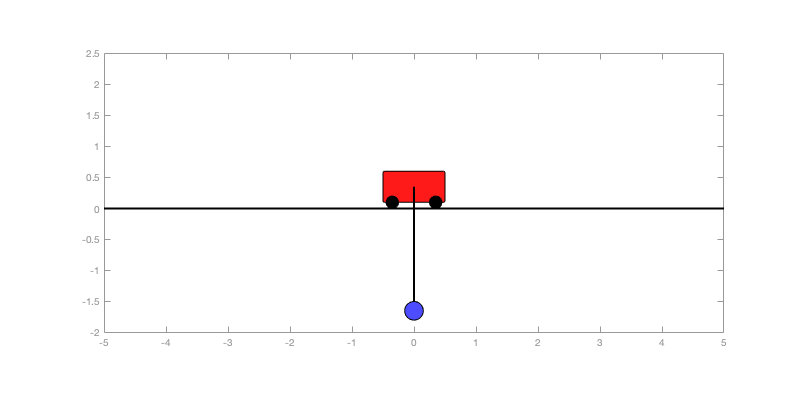

figure(1); clf
draw_cartpole(y0([1 3 2 4]),params)

### Solve DAEs Using ode15i

[tSol, ySol] = ode15i(F_DAE, [0 2], y0, yp0, opt);

Plot solution

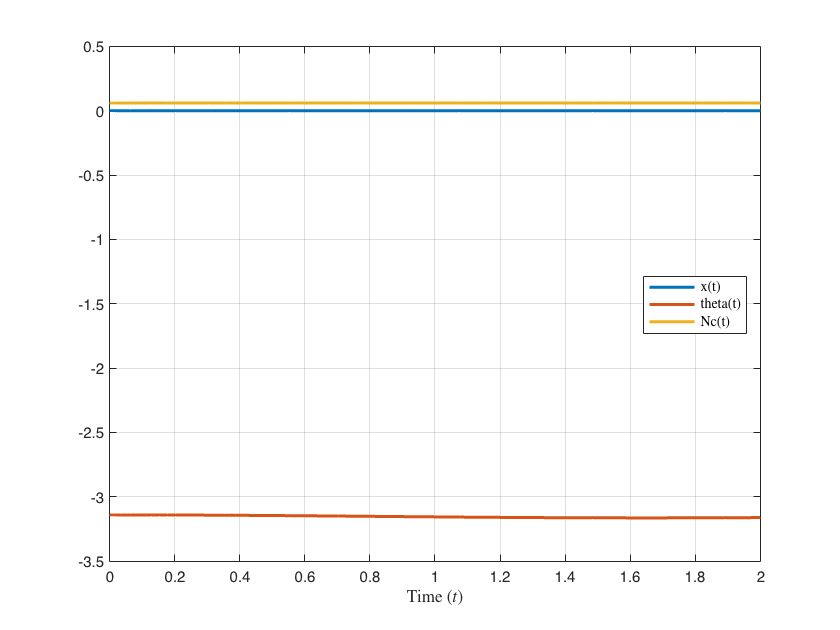

figure(2); clf
plot(tSol, ySol(:, 1:origVars), 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
legend(labels, 'Location', 'Best', 'Interpreter', 'latex')
grid on

### Save results to file

labels = arrayfun(@(i) char(DAEvars(i)), 1:numel(DAEvars), 'UniformOutput', false);
sim_results = array2table([tSol ySol], 'VariableNames', [{'t'} labels]);
filename = "cartpole_benchmark_sim.csv";
writetable(sim_results, fullfile(results_dir, filename))

### Solve using function script file

Solve the equations using the function script created by `daeFunction` above and check results are identical.

% Solve DAEs
F_DAE2 = @(t, Y, YP) cartpoleDAEFunction(t, Y, YP, F, g, l, mc, mp, muc, mup);
[tSol2, ySol2] = ode15i(F_DAE2, [0 2], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)

Solve using the function in cartpole_DAEs.m

% Solve DAEs
F_DAE2 = @(t, Y, YP) cartpole_DAEs(t, Y, YP, params);
[tSol2, ySol2] = ode15i(F_DAE2, [0 2], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)